warning off
init_deconvolution


Adding toolboxes and subfolders to path...

projectFolder = /net/store/nbp/users/behinger/projects/deconvolution/git

warning on

# Introduction

Subjects are exploring a face stimulus. Using an eyetracker and the EEG-Eye toolbox we add markers of saccade onsets into our EEG-Data. The data were cleaned for eye-movement related artefacts using ICA.

In this tutorial we try to disentangle stimulus related ERPs and (micro)saccade related ERPs.

PROJECTPATH = '/media/behinger/6ECEC8DFCEC8A127/deconvolution/application_microsaccades/';
EEG = pop_loadset('filename','msaff_15.set','filepath',sprintf('%s/02_sync_data_with_sacc',PROJECTPATH));

pop_loadset(): loading file /media/behinger/6ECEC8DFCEC8A127/deconvolution/application_microsaccades/02_sync_data_with_sacc/msaff_15.set ...
Reading float file '/media/behinger/6ECEC8DFCEC8A127/deconvolution/application_microsaccades/02_sync_data_with_sacc/msaff_15.fdt'...


% there where ~2% saccades with extreme values. We remove it for this demonstration
EEG = eeg_checkset(EEG);
badEv = find([EEG.event.sac_amplitude]>10);
EEG.event(badEv) = [];

% A simple threshold function taken from ERPLAB
winrej = dc_continuousArtifactDetect(EEG,'amplitudeThreshold',250);


	So, basicrap.m will be applied over the full range of data.

Please wait. This might take several seconds...

 87 segments were marked.



% We remove very noisy data segments (>250mV) from the designmatrix

# Defining the design

cfgDesign = [];
cfgDesign.eventtype = {'saccade'}; % we only model a single event to make the tutorial easier.
% We use intercept-only formulas because we are only interested in the overlap for now
cfgDesign.formula = {'y ~ 1 + spl(sac_amplitude,10)'}; % 10 splines are a lot, but very high amplitude saccades (>5deg) and small ones (<1deg) show very different behaviour
EEG = dc_designmat(EEG,cfgDesign);

Modeling event(s) [saccade] using formula: y ~ 1 + spl(sac_amplitude,10) 


The intercept for the effect sac_amplitude has its peak at 2.131479


We can visualise the set of splines we are using:

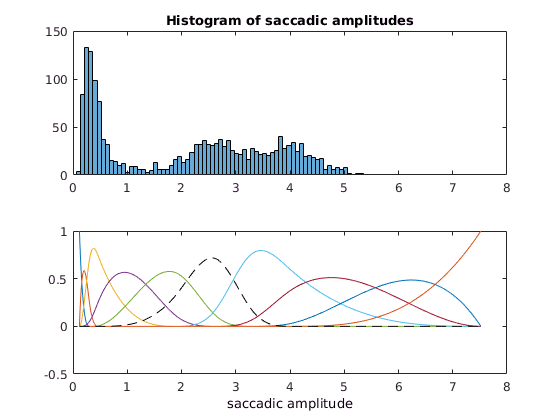

spl = EEG.deconv.predictorSplines{1};
subplot(2,1,1),histogram(spl.paramValues,100),title('Histogram of saccadic amplitudes')
subplot(2,1,2),plot(spl.spline2val,spl.basis),xlabel('saccadic amplitude')
% One spline is missing in the basis-set, this is incorporated in the intercept. To recover its shape we use a linear transformation
hold on, plot(spl.spline2val,1-sum(spl.basis,2),'k--')

The term `spl(sac_amplitude,10)` creates 10 splines over our predictor. The default setting is to put the splines at points of the quantiles of the variable. This ensures that in regions with a lot of data, lots of splines are generated and in regions with sparse data,  broad splines are used. One could also put the splines in a linear or logarithmical way.

The later procedure will fit one beta to each spline (resulting in 9 spline-betas + 1 intercept-beta).

cfgTimeshift = [];
cfgTimeshift.timelimits = [-.3,0.8];

EEG = dc_timeshiftDesignmat(EEG,cfgTimeshift);


dc_deconvolveDesignmat(): Timeshifting the designmatrix...
...done


EEG = dc_continuousArtifactExclude(EEG,struct('winrej',winrej));


removing 10.9% from design matrix (fill it with zeros) 


EEG= dc_glmfit(EEG,'channel',[32]);


dc_glmfit(): Fitting deconvolution model...solving the equation system

solving electrode 32 (of 1 electrodes in total)

... took 45.3s
 LMfit finished 


# Plot the results

Currently the spline-predictor is still separated in intercept + 10 spline-betas. The relationship for e.g. the P100 can be visualized like this:

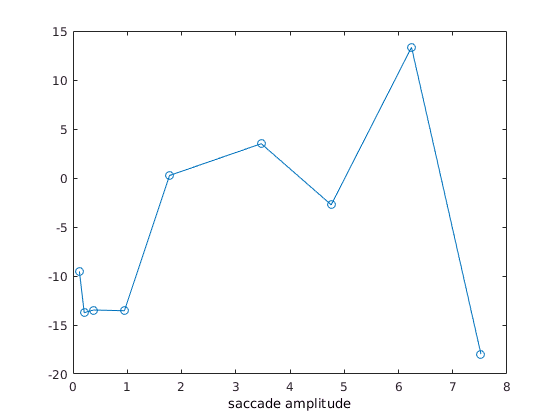

unfold= dc_beta2unfold(EEG,'convertSplines',0);
figure
splineix = find(cellfun(@(x)strcmp(x.name,'sac_amplitude'),unfold.deconv.predictorSplines)); % a bit pointless for only 1 spline

sac_amp_ix = cellfun(@(x)~isempty(x),(strfind({unfold.epoch.name},'sac_amplitude'))); % get all betas related to sac_amplitude
timeix = get_min(0.115,unfold.times); % somewhere around the p100

x = cellfun(@(x)str2num(x(end-3:end)),{unfold.epoch(sac_amp_ix).name});
plot(x,squeeze(unfold.beta(32,timeix,sac_amp_ix)),'-o'),xlabel('saccade amplitude')

This plot is still lacking the intercept and in generall is somewhat missleading, because the underlying basis functions are overlapping with different overlaps. In order to get a better picture, let's multiply the betas with the basis function to get an estimate in the predictor-value-domain.

figure,
% note that unfold.beta now has size 1002! the spline conversion returned values for a densily packed linear domain over all parameter values.
unfold= dc_beta2unfold(EEG,'convertSplines',1);

Elapsed time is 0.624830 seconds.


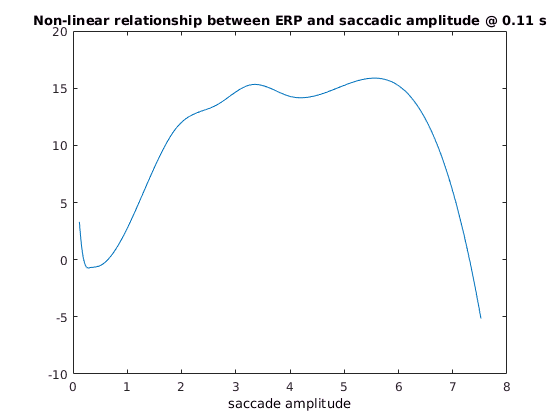

x = unfold.deconv.predictorSplines{splineix}.spline2val; % the values of the basis function

sac_amp_ix = cellfun(@(x)~isempty(x),(strfind({unfold.epoch.name},'sac_amplitude'))); % get all betas related to sac_amplitude
y = unfold.beta(32,timeix,sac_amp_ix); 
% we could add the intercept, but it is just a constant offset
 y = y + unfold.beta(32,timeix,1);
plot(x,squeeze(y)),xlabel('saccade amplitude'),title(sprintf('Non-linear relationship between ERP and saccadic amplitude @ %.2f s',unfold.times(timeix)))

plotting all parameters


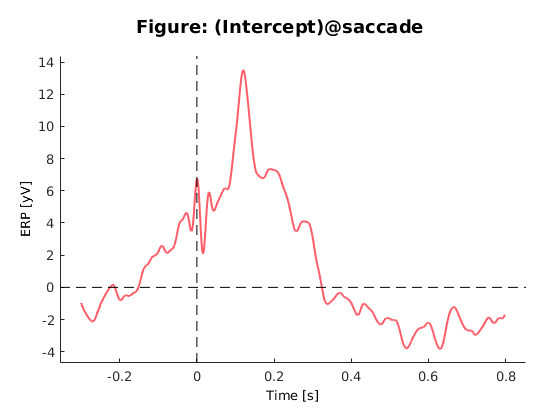

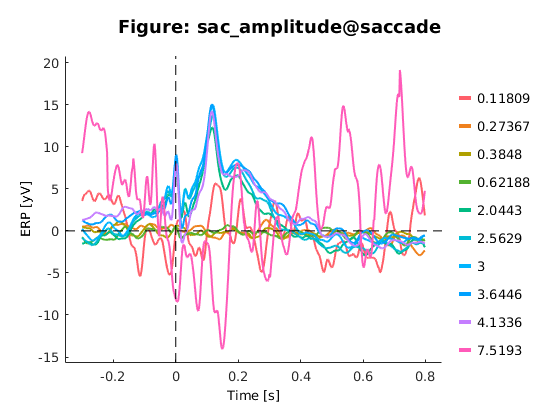

% The default parameters plot the predictor at its quantiles
dc_plotParam(unfold,'chan',32,'plotSeparate','all','add_intercept',1);

The upper panel is the response to the average saccade amplitude. The lower one split up by saccade amplitude.

Two important notes to this plot:

a) There are outliers/bad estimates at the extremes. In the upper example the pink-curve has a very high noise level. This is because the last spline is only informed by a small amount of trials, it is usually highly unstable.

b) The lines represent saccade-amplitudes at the quantiles of the saccade amplitude distribution.

In order to get a more representative picture, we can utilize the `'pred_value' `option in the plot and put a linear spacing excluding the extremata

plotting all parameters


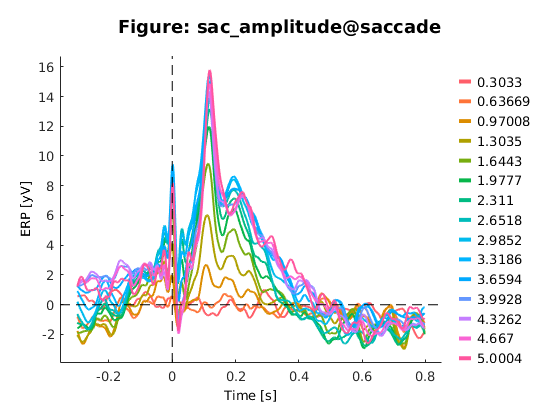

dc_plotParam(unfold,'chan',32,'plotSeparate','all','add_intercept',1,'pred_value',{{'sac_amplitude',linspace(0.3,5,25)}})